Author： 黃仕鈞

# Reclaim the Autoregressive Model

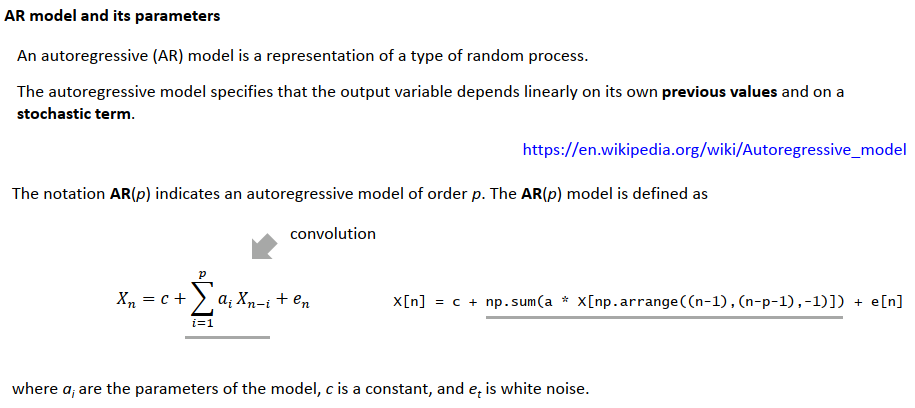

NBE_Aalto University_neuroscience_course

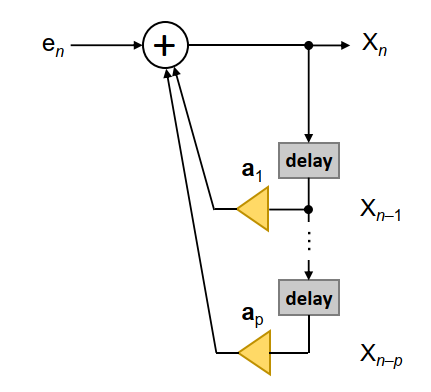


$$X_n =c+\sum_{i=1}^p a_i X_{n-i} +e_n$$


# Distortion Rate

[RATE DISTORTION STUDY FOR TIME-VARYING AUTOREGRESSIVE GAUSSIAN PROCESS](https://arxiv.org/abs/1910.14228)


$$x_t =-\sum_{m=1}^M a_m \left(r\right)x_{t-m} +z_t ,\;\textrm{for}\;t=1,2,\dots ,N$$


- $r=\;\frac{t}{N}$  is defined as distortion rate.


$$g(r,\omega )=\frac{1}{\sigma_z^2 }{\left|1+\sum_{m=1}^M a_m (r)e^{-jm\omega } \right|}^2$$


Use [Anonymous Function](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) + ( f[ucntion](https://www.mathworks.com/help/matlab/ref/function.html), or insert by [struct](https://www.mathworks.com/help/matlab/ref/struct.html))  and set the integral description.

And a important skill is add generator string to Anonymous Fcn, design it for nested loops.

$D_{\theta } =\frac{1}{2\pi }\int_{-\pi }^{\pi } \int_0^1 \mathrm{min}\left\lbrack \theta ,\frac{1}{g(r,\omega )}\right\rbrack drd\omega$, iteration > 1, need past value

- $\theta$ is upper threshold, set to 0.1 close to 0

$R\left(D_{\theta } \right)=\frac{1}{2\pi }\int_{-\pi }^{\pi } \int_0^1 \mathrm{max}\left\lbrack 0,\frac{1}{2}\mathrm{log}\frac{1}{\theta \times (r,\omega )}\right\rbrack drd\omega$, iteration >1, need past value

-  0 is low limit

clear all; clc;
% parameter
N = 50; % quantity of samples
e = randn(N);
e = e / max(e);

% es = sin((1:N))+ sin((1:N).*2+10); % add sin sin wave
% e = 1./6.*(es'+e); % es' is transpose result of es

a = [];
sets = 5; % test sets
lag = 30; % AR(p) p is lag

% Generate the a(r) AR is not able to linear regression but just test
% time varying a --> design varying a
for i = 1:N
    a(i) = (i/N); 
end
ac = zeros(sets,1);
ac = [0.1, 0.9, -0.9 ,0.3, 0.5]; % with constant close to 0, 1...

x = zeros(N,sets);
xc = zeros(N,sets); % 初始化矩陣大小 constant

for j =1:lag % lag not calc
    for i = 1:5 % which data
        x(j,i) = e(j); % a(i).*x(j,i)+e(j);
        xc(j,i) = e(j); % ac(i).*x(j,i)+e(j);
    end
end

for j = 1:sets % lag+1 這裏只有一筆資料，無法積分
    i = lag +1;
    xc(i,j) = ac(j).*x(i-lag,j)+e(i); % 對照組 constant a
    x(i,j) = a(i).*x(i-lag,j)+e(i);
    
end

for j = 1:sets % 這裏開始計算distortion rate N-lag-1 筆資料
    for i = (2+lag):N % calc start from AR(p->lag) --> lag+2
        xc(i,j) = ac(j).*x(i-lag,j)+e(i); % 對照組 constant a
        x(i,j) = a(i).*x(i-lag,j)+e(i);
        g_struct = struct('sets_index_now',j,'data_index_now',i,'lag_p',lag,...
            'samples',N, 'varing_gain',a,'predict',x,'input',e );
        sigma = zeros(1,i); theta = zeros(1,i); r = zeros(1,i); omega = zeros(1,i);
        sigma(i) = var(g_struct.predict(:,1)); % get the varience
        theta(i) = max(g_struct.predict(:,1)) - sigma(i)./4; % 暫時這麼算 上限 upper threshold
        r(i) = g_struct.varing_gain(i);
        omega(i) = 2.71828;
        %D_theta = @(r,w) 1./( 1./(sigma(i).^2).* abs(1 + sum(1 + s(i,:).*exp(-j.*length(s(i,:)).*w))).^2 ); 
        
    end
end
% calc end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%     Calc approach ways    %%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This block not calculate
% in 2020 MATLAB the function can be defined in the same file
% x(i,j) = a(i).*x(i-lag,j)+e(i);
% s = struct(field1,value1,field2,value2,field3,value3,field4,value4)
% 枚舉的 field 儘量有意義一點
% call by s.field1 or s(1) it will get te value
% x(j,i) = a(i).*x(i-lag,j)+e(i); from this seris x(:,1)
s = x(:,1); % input_seris  x(:,1), x(:,2) is the same...
s = zeros(N-lag,N); % it's size initial
s(i,:) = x(:,1); % input_seris  x(:,1), x(:,2) is the same...
sigma(i) = var(x(:,1)); % get the varience
theta(i) = max(s(i,:)) - sigma(i)./4; % 暫時這麼算 上限 upper threshold
r(i) = a(i);
omega(i) = 2.71828;
% after summarize above
% we knoow it need i, j, lag, N, x, a, e,  for our calc integral
g_struct = struct('sets_index_now',j,'data_index_now',i,'lag_p',lag,...
    'samples',N,'predict',x,'input',e )

g_struct = struct with fields:
    sets_index_now: 5
    data_index_now: 50
             lag_p: 30
           samples: 50
           predict: [50×5 double]
             input: [50×1 double]



g(i) = 1./(sigma(i).^2).* abs(1 + sum(1 + s(i,:).*exp(-j.*length(s(i,:)).*omega(i)))).^2;% omega暫時用2.71828
% D function 其他略，看上面s的部分要用struct array 加上字串處理設計出積分的項並做成匿名函數，新的iter會多一項要積分
%D_theta = @(r,w) 1./( 1./(sigma(i).^2).* abs(1 + sum(1 + s(i,:).*exp(-j.*length(s(i,:)).*w))).^2 ); 
%D(i) = integral2(fun,0,1,-pi,pi);
%R(i) = integral2(fun,xmin,xmax,ymin,ymax);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


$$g(r,\omega )=\frac{1}{\sigma_z^2 }{\left|1+\sum_{m=1}^M a_m (r)e^{-jm\omega } \right|}^2$$



$$D_{\theta } =\frac{1}{2\pi }\int_{-\pi }^{\pi } \int_0^1 \mathrm{min}\left\lbrack \theta ,\frac{1}{g(r,\omega )}\right\rbrack drd\omega$$


- $\theta$ is upper threshold, set to 0.1 close to 0


$$R\left(D_{\theta } \right)=\frac{1}{2\pi }\int_{-\pi }^{\pi } \int_0^1 \mathrm{max}\left\lbrack 0,\frac{1}{2}\mathrm{log}\frac{1}{\theta \times (r,\omega )}\right\rbrack drd\omega$$


-  0 is low limit

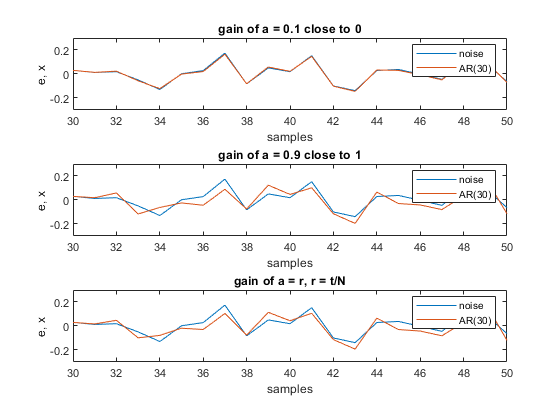


str1 = ['AR', '(', string(lag), ')' ];
t = linspace(1,N,N);
ylimit_const = [-0.3, 0.3];
AR = sprintf( str1(1)+str1(2)+str1(3)+str1(4));

figure();
subplot(3, 1, 1);
plot(t(lag:end),e(lag:end));
hold on;
plot(t(lag:end),xc(lag:end,1));
title('gain of a = 0.1 close to 0');
xlim([lag, N]); %xlim(0, N);
ylim(ylimit_const); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', AR)
subplot(3, 1, 2);
plot(t(lag:end),e(lag:end));
hold on;
plot(t(lag:end),xc(lag:end,2));
title('gain of a = 0.9 close to 1')
xlim([lag, N]); %xlim(0, N);
ylim(ylimit_const); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', AR)
subplot(3, 1, 3);
plot(t(lag:end),e(lag:end));
hold on;
plot(t(lag:end),x(lag:end,1));
title('gain of a = r, r = t/N')
xlim([lag, N]); %xlim(0, N);
ylim(ylimit_const); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', AR)

# Matlab Deal the prob

Matlab Deal the prob with Anonymous Function (匿名函式), can solve the nested code.

- [anonymous function   = @(x) exp(-x);      = @(x,y) exp(x)+y](https://www.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html)

- [integral(anon_fun, -inf, inf)](https://www.mathworks.com/help/matlab/ref/integral.html)

- [integral2(anon_fun, -inf,inf,  -inf, inf) double integral](https://www.mathworks.com/help/matlab/ref/integral2.html)

# Integral Source may from:

```m

% [Trapezoidal numerical integration](https://www.mathworks.com/help/matlab/ref/trapz.html) to do it

y = sin(t)

trapz(t,y) %

trapz(x)  % x is meshgrid() result

%  inf -inf prob will failed

```

# MonteCarlo approach of the inf -inf prob

But can't deal the $\int_{-\infty }^{\infty } \frac{f(x)}{g(x)}$, if g(x) have log() or exp(), still the problems for me

目前只會用Matlab做這類積分, 因爲匿名函數整合的很好

可以想想如何用trapz做，pytorch出來之後可以

使用torch.meshgrid(), torch.trapz()，並使用GPU進行計算，

Pytorch厲害在可以使用AMD和NVIDIA GPU進行這些動作。

自己做的話，積分問題還不太瞭解做法。

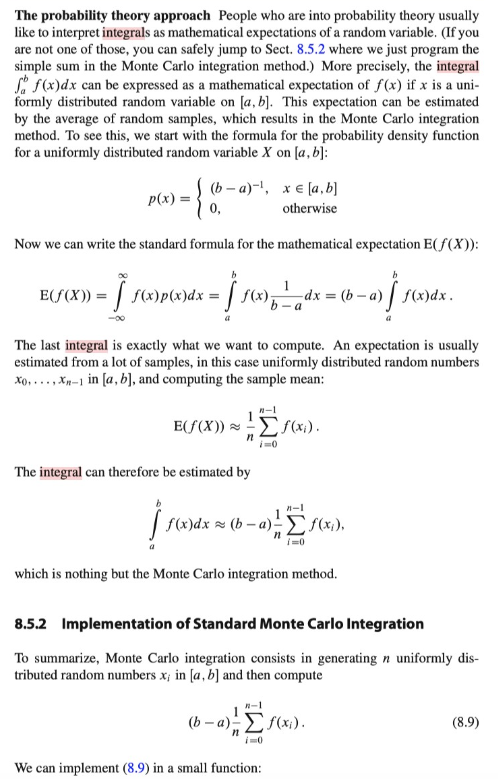

之前Llodmax 計算就會